clear all
close all

%Universal constants
kappa   = 0.41     ;%von-Karman constant
g       = 9.81     ;%Gravitational acceleration (m/s^2)
Omega   = 0.729e-4 ;%Earth's rotation rate (1/s)

%Temperature profile properties
Theta0     = 265                       ;%K
lapse_rate = 0.001                     ;%K/m
Cr         = -1/3600                   ;% Surface potential temperature Cooling rate (K/s)
N_infty    = sqrt(g/Theta0*lapse_rate) ;%Brunt Vaisala frequency

%Geostrophic wind velocity and Coriolis frequency
G          = 15                ; %Geostrophic wind speed
phi        = 43.4              ; %latitude angle
fc         = 2*Omega*sind(phi) ; %Coriolis frequency

%Zilitinkevich number
muN        = N_infty/fc;

%Model constants for Turbulence Intensity
A1_const   = -0.25    ; %Townsend-Perry constant
B1_const   =  0.60    ;

%Grid parameters
Nx=200;
Ny=250;
Nz=500;

Lx=3000;%m
Ly=1500;%m
Lz=2000;%m

x=linspace(0,Lx,Nx);
y=linspace(-Ly/2,Ly/2,Ny);

z0=0.1;%surface roughness (m)
z_log=logspace(log10(z0),log10(Lz),Nz);
z_linear=linspace(0,Lz,Nz); 

%Wake model parameters 
x_array  = zeros(Nx,1);
y_array  = zeros(Ny,1);
xo_array = zeros(1 ,1);
sigma2_x = zeros(Nx,1);
du_mag_x = zeros(Nx,1);
du0_mag_x= zeros(Nx,1);
Xe_w_a   = zeros(1 ,1);
kw_model = zeros(1 ,1);

kw_z_model           = zeros(Nz, 1);
t_hat_xz             = zeros(Nx,Nz);
yc_majid_xz          = zeros(Nx,Nz);
yc_CVP_majid_xz      = zeros(Nx,Nz);
yc_g_majid_xz        = zeros(Nx,Nz);
theta_angle          = zeros(Nx,Ny,Nz);
xi_dim               = zeros(Nx,Ny,Nz);
xi0_theta            = zeros(Nx,Ny,Nz);
sigma_width          = zeros(Nx,Ny,Nz);
sigma_width_Gaussian = zeros(Nx,Ny,Nz);
yc_Veer              = zeros(Nx,Nz);

X_root=0;

%Turbine parameters
D         = 100      ; %Diameter of wind turbine (m)
Radius    = D/2      ; %Radius
Ct_prime  = 1.33     ; %local thrust coefficient
yaw_angle = 20*pi/180 ; %yaw angle
zt        = 100      ; %m hub height

%Evaluate Gesotrphic Drag Law to compute Ug,Vg,h_ABL,ustar
eps_tol    = 1e-8;
[Ug,Vg,ustar,h_ABL,mu,epsilon]=GDL_ABL_model(G,fc,z0,Cr,Theta0,lapse_rate,eps_tol)

Ug = 11.9079

Vg = -9.1215

ustar = 0.3484

h_ABL = 199.2279

mu = 168.5034

epsilon = 2.0188e-09

Cg    = 1.43;
Gamma = 0.83;
cm    = 0.2;

xi_hat       = z_log*fc/ustar;
xi_hat_0     = z0*fc/ustar;
h_hat        = h_ABL*fc/ustar;
xi_hat_m     = cm*h_hat;
g_func       = Cg*(1-exp(-xi_hat/Gamma/h_hat));
g_prime_func = (Cg/Gamma/h_hat).*exp(-xi_hat/Gamma/h_hat);

U_profile    = zeros(Nz,1);
V_profile    = zeros(Nz,1);
U_inner      = zeros(Nz,1);
U_outer      = zeros(Nz,1);


idx=double(xi_hat/h_hat>=cm);
idx_n=double(~idx);

U_inner = ((1/kappa)*log(xi_hat/xi_hat_0)+(5*mu+0.3*muN)*(xi_hat-xi_hat_0))*ustar;

U_outer = (-g_prime_func.*(1-xi_hat/h_hat).^(3/2) ...
         +g_func.*(3/2/h_hat).*(1-xi_hat/h_hat).^(1/2)+Ug/ustar)*ustar;

V_profile= ((g_func.*g_prime_func)./(sqrt(1-g_func.^2)).*(1-xi_hat/h_hat).^(3/2) ...
                  +(3/2/h_hat).*sqrt(1-g_func.^2).*(1-xi_hat/h_hat).^(1/2)+Vg/ustar)*ustar;

U_profile = U_outer.*idx + U_inner.*idx_n;

idx=(xi_hat/h_hat>=1);
V_profile(idx)=Vg;
U_profile(idx)=Ug;

%Interpolate U,V onto linear z-grid
U_profile_linear=interp1(z_log,U_profile,z_linear);
V_profile_linear=interp1(z_log,V_profile,z_linear);

%Find location and index of hub height
[zt_val,zt_loc]=min(abs(z_linear-zt));
z_linear(zt_loc)

ans = 100.2004


%Rotate U,V profiles such that V(z_hub)=0 to ensure streamwise aligned mean
%flow at hub height
angle=atan2(V_profile_linear(zt_loc),U_profile_linear(zt_loc));
U_profile_linear_rot =  U_profile_linear*cos(angle) + V_profile_linear*sin(angle); 
V_profile_linear_rot = -U_profile_linear*sin(angle) + V_profile_linear*cos(angle); 

%Find hub height velocity
U_hub=U_profile_linear_rot(zt_loc)

U_hub = 14.3077

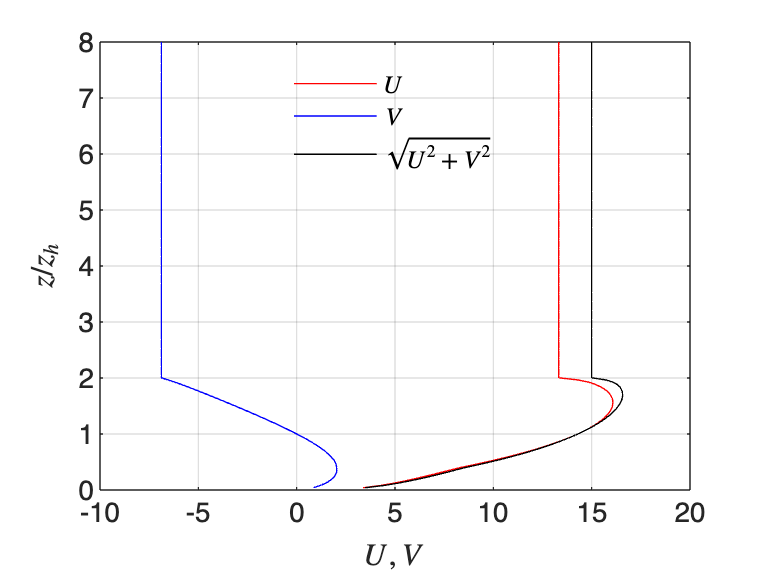

%Plot rotated velocity profile on z_linear grid
close all
plot(U_profile_linear_rot,z_linear/zt,'r');hold on
plot(V_profile_linear_rot,z_linear/zt,'b');
plot(sqrt(U_profile_linear_rot.^2+V_profile_linear_rot.^2),z_linear/zt,'k');
legh=legend('$U$','$V$','$\sqrt{U^2+V^2}$');
set(legh,'interpreter','latex','location','North');
legend box off
xlabel('$U,V$','Interpreter','latex');
ylabel('$z/z_h$','Interpreter','latex')
ylim([0 8])
grid on

**Compute **$C_T, a, A_*, \tilde{\xi}_0=R\sqrt{A_*}

$


$$C_T=\frac{16 C_T^\prime}{(4+C_T^\prime cos^2\beta)^2}$$



$$A_*=\frac{1+\sqrt{1-C_T\cos^2\beta}}{2\sqrt{1-C_T \cos^2\beta}}$$


Ct=16*Ct_prime/(4+Ct_prime*(cos(yaw_angle))^2)^2;
a_ind = 0.5*(1 - sqrt(1-Ct*(cos(yaw_angle))^2))

a_ind = 0.2270

A_star=(1+sqrt(1-Ct*(cos(yaw_angle))^2))/(2*sqrt(1-Ct*(cos(yaw_angle))^2));
xi0_tilde=Radius*sqrt(A_star);

**Maximum velocity deficit function: **$C(x)=\Delta u_{max}/U_h$ 


$$ C(x)=
\begin{cases}
2a & x\leq x_0,\\
1-\sqrt{1-\frac{C_T\cos^3\beta}{2\tilde{\sigma}^2(x)/R^2}}    & x\geq x_0
\end{cases}.$$



$$\tilde{\sigma}^2(x)=(k_w  x+0.4 R\sqrt{A_*})(k_w  x+0.4 R\sqrt{A_*}\cos\beta)$$


$x_0$** is transition location from potential core region to the region where velocity deficit decays downstream the wind turbine**


$$x_0 = \frac{1}{5 k_w} \Biggl(\sqrt{R^2 A_*(1-\cos\beta)^2 +25 \frac{R^2}{2}\frac{C_T\cos^3\beta}{(1-(1-2a)^2)}}
+R\sqrt{A_*} (1-\cos \beta)\Biggr)-\frac{2}{5k_w}R\sqrt{A_*}$$
 

%Set kw model type
%model_type=1 =====> kw=0.05
%model_type=2 =====> kw=0.075
%model_type=3 =====> kw=( 0.021^6 + (0.33*Iu_zh)^6 )^(1/6)

model_type=3;

[Cx,A_star,xo,kw]= Cx_func(yaw_angle,Ct,Radius, ...
                               ustar, ...
                               U_hub,zt, ...
                               h_ABL, ...
                               x, ...
                               A1_const, ...
                               B1_const,model_type);

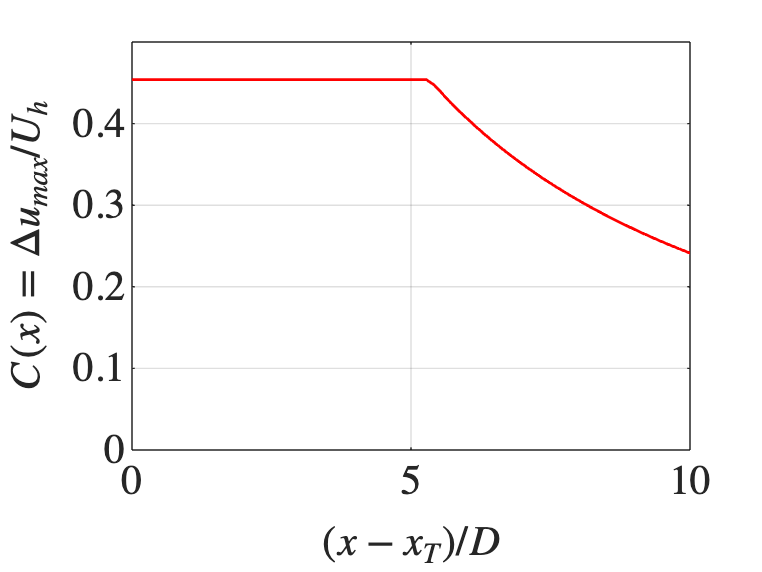

%Plot and check Cx
close all
figure
plot(x/D,Cx,'LineWidth',1,'Color','r');hold on

set(gca,'fontsize',15,'fontname','Times');
xlabel('$(x-x_T)/D$','Interpreter','latex','FontSize',15);
ylabel('$C(x)=\Delta u_{max}/U_h$','Interpreter','latex','FontSize',15);
ylim([0 0.5])
xlim([0 10])
grid on

Evaluate  $\hat{t}(x,z)$


$$ 


\hat{t}(x,z)\approx-1.44\frac{U_h}{u_*}\frac{R}{R\sqrt{A_*}}C_T\cos^2\beta\sin\beta 
 \,\, \left[1-\exp\left(-0.35\frac{u_*}{U(z)}\frac{x}{R}\right)\right]$$


t_hat_xz(:,:)  = t_hat_xz_func(yaw_angle,Ct,Radius,A_star, ...
                                          ustar, ...
                                          U_hub,zt, ...
                                          h_ABL, ...
                                          x,z_linear,...
                                          U_profile_linear_rot,...
                                          V_profile_linear_rot);
max(t_hat_xz(:)),min(t_hat_xz(:))

ans = 0

ans = -10.5647

**Wake displacement**


$$y_c(x,z)=\hat{y}_c(\hat{t})R\sqrt{A_*}+y_{c,\text{veer}}$$



$$\hat{y}_c(\hat{t})=\frac{(\pi-1)|\hat{t}|^3+2\sqrt{3}\pi^2\hat{t}^2+48(\pi-1)^2|\hat{t}|}{2\pi(\pi-1)\hat{t}^2+4\sqrt{3}\pi^2|\hat{t}|+96(\pi-1)^2}\text{sgn}(\hat{t}) -\frac{2}{\pi}\frac{\hat{t}}{[(z+z_h)/R\sqrt{A_*}]^2-1}$$


[yc_majid_xz(:,:),yc_CVP_majid_xz(:,:),yc_g_majid_xz(:,:)] = yc_func(t_hat_xz(:,:), ...
                                                                     Radius,A_star,zt, ...
                                                                     x,z_linear);
for i=1:Nx
    for k=1:Nz
        yc_Veer(i,k)=x(i)*V_profile_linear_rot(k)/U_profile_linear_rot(k);
    end
end

[max(yc_majid_xz(:)),min(yc_majid_xz(:))]

ans =     1.0450 -118.7548


**Polar angle**


$$  \theta=\tan^{-1}\left(\frac{z-z_h}{y-\hat{y}_c(\hat{t})R\sqrt{A_*}}\right)$$


theta_angle(:,:,:) = theta_func(x,y,z_linear,zt,yc_majid_xz(:,:));

**Wake shape function:** $\xi(\theta,x) =  \xi_0(\theta) \, \hat{\xi}(\theta,\hat{t})$

**Initial wake shape:** $\xi_0(\theta)=R\sqrt{A_*}\frac{|\cos\beta|}{\sqrt{1-\sin^2\beta\sin^2\theta}}$

**Dimensionless wake shape function:** $\hat{\xi}(\theta,\hat{t})=1-\alpha\biggl[
\frac{1}{2}\tanh\left(\frac{\hat{t}^{2}}{4\alpha}\right)\cos2\theta
-\frac{1}{4}\tanh\left(\frac{\hat{t}^{3}}{8\alpha}\right)\cos(3\theta)
-\frac{5}{48}\tanh\left(\frac{\hat{t}^{4}}{16\alpha}\right)\cos(2\theta)
+\frac{7}{48}\tanh\left(\frac{\hat{t}^{4}}{16\alpha}\right)\cos(4\theta)  \biggr], \ \alpha=1.263$

[xi_dim(:,:,:), xi0_theta(:,:,:)] = wake_shape_func(yaw_angle,A_star,Radius,...
                                                    x,y,z_linear, ...
                                                    theta_angle(:,:,:),...
                                                    t_hat_xz(:,:));


**Wake width:** $\sigma(\theta,x) = k_w \, x + 0.4 \, \xi(\theta,x)$

for i=1:Nx
    for j=1:Ny
        for k=1:Nz
            sigma_width(i,j,k) = kw*x(i)+0.4*xi_dim(i,j,k);       
        end
    end
end

**Velocity deficit**


$$\frac{\Delta u}{U_h} = C(x) \exp\left[-\frac{(y-y_c)^2+(z-z_h)^2}{2\ \sigma(\theta, x)^2}\right]$$


du_model = zeros(Nx,Ny,Nz);
for i=1:Nx
    for j=1:Ny
        for k=1:Nz
            du_model(i,j,k) = Cx(i).*exp(-((y(j)-yc_majid_xz(i,k)-yc_Veer(i,k)).^2+(z_linear(k)-zt).^2)./(2*sigma_width(i,j,k)^2));
        end
    end
end

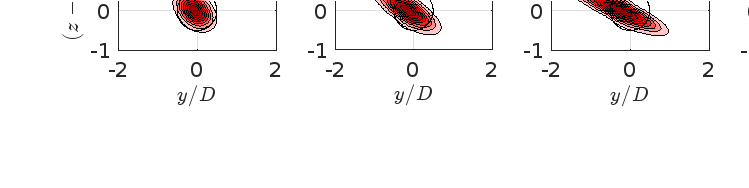

%Visualize velocity deficit contours
set(groot, 'DefaultFigureVisible', 'on');

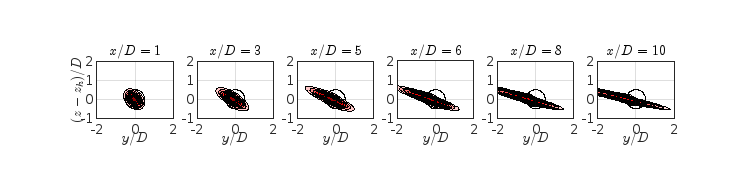

close all
figure
set(gcf,'Color','w','Units','Centimeters','Position',[10 10 40 10]);
xloc_array=[8:12:70];
num_plots = numel(xloc_array);
[x_circ, y_circ] = computeCircle(0,0, Radius/D, Nx);

for k = 1:num_plots
    i = xloc_array(k);
    ax=subplot(1, num_plots, k); % Use subplot

    contourf(y/D,(z_linear-zt)/D,squeeze(du_model(i,:,:))',8,'LineStyle','-');hold on
    plot(x_circ,y_circ,'k','linewidth',1);
    set(gca,'DataAspectratio',[1 1 1]); % Use gca for current axes
    set(gca,'fontsize',10,'fontname','Times'); % Reduced fontsize for fitting
    colormap(bluewhitered);
    caxis([0 max(Cx)]);

    % if k == num_plots
    %   cb=colorbar;
    %   cb.Ticks=linspace(0,max(Cx),5);
    %   cb.Ruler.TickLabelFormat = '%.2f';
    %   ylabel(cb,'$\Delta u/U_h$','interpreter','latex');
    % end
    xlim([-2 2]);
    ylim([-1 2]);
    title(sprintf('$x/D=%0.0f$',x(i)/D),'interpreter','latex','FontSize',10); % Reduced fontsize

    xlabel('$y/D$','Interpreter','latex','FontSize',10);
    if k == 1
      ylabel('$(z-z_h)/D$','Interpreter','latex','FontSize',10);
    end
    grid on
end